# Technical Project Foundations of Robotics

close all
clear
clc

## SCARA's Parameters

scara_parameters;

## SCARA

%It is necessary to execute this instruction to start Peter Corke's
%Robotics Toolbox
startup_rvc

Robotics, Vision & Control: (c) Peter Corke 1992-2020 http://www.petercorke.com
- Robotics Toolbox for MATLAB (release 10.4)
 - ARTE contributed code: 3D models for robot manipulators (C:\Program Files\MATLAB\R2023b\toolbox\rvctools\robot\data\meshes)
 - pHRIWARE (release 1.2): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2024) (c)
- Machine Vision Toolbox for MATLAB (release 4.3)
 - VGG contributed code (C:\Program Files\MATLAB\R2023b\toolbox\rvctools\contrib\vgg)
 - graphseg contributed code (C:\Program Files\MATLAB\R2023b\toolbox\rvctools\contrib\graphseg)
- Spatial Math Toolbox for MATLAB (release 1.0)



%SCARA
L(1) = Link('d',d1,'a',a1,'alpha',alpha1);
L(2) = Link('d',d2,'a',a2,'alpha',alpha2);
L(3) = Link('theta',theta3,'a',a3,'alpha',alpha3);
L(4) = Link('d',d4,'a',a4,'alpha',alpha4);

L(3).qlim = [0 1]; % Joint Variable Limits [min max]
                    %Obviously, the manipulator cannot go below 1 meter
                    %since its height is exactly 1 meter

scara = SerialLink(L, 'name', 'SCARA');

scara.base = transl(0, 0, d0);

## Manipulability Ellipsoids

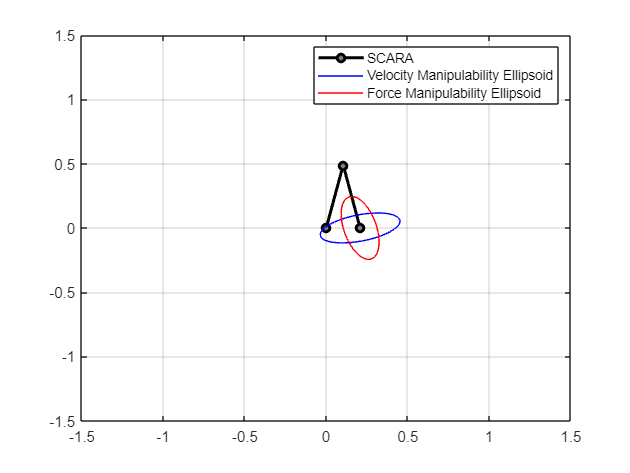

%Test Poses
qt1 = [pi/(3/1.3) -pi/(3/1.3/2) 0.5 0];
qt2 = [pi/3 -pi/(3/2) 0.5 0];
qt3 = [pi/6 -pi/3 0.8 0];
qt4 = [pi/12 -pi/6 0.8 0];
qt5 = [pi/20 -pi/10 0.8 0];
qt6 = [pi/30 -pi/15 0.7 0];

%Manipulability Ellipsoids
%Execute one istruction at a time because the Robotics Toolbox does not
%save previous pose for 3D plotting
ellipsoids(scara,qt1);

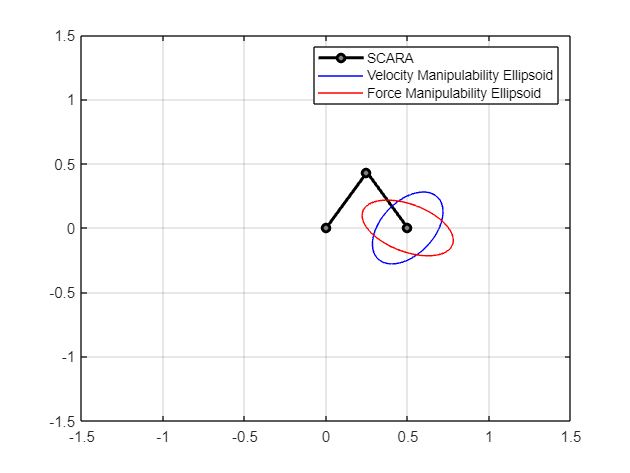

ellipsoids(scara,qt2);

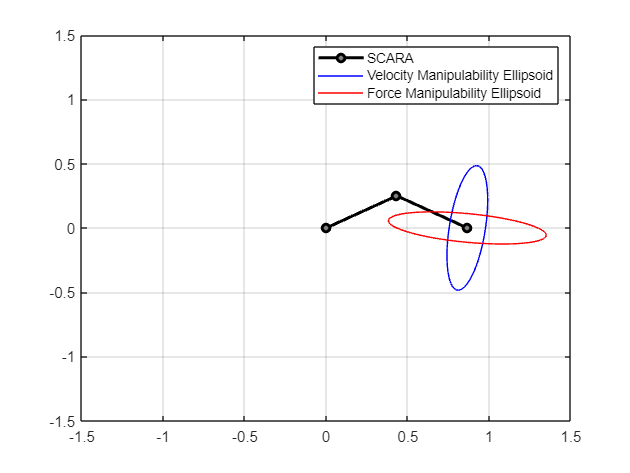

ellipsoids(scara,qt3);

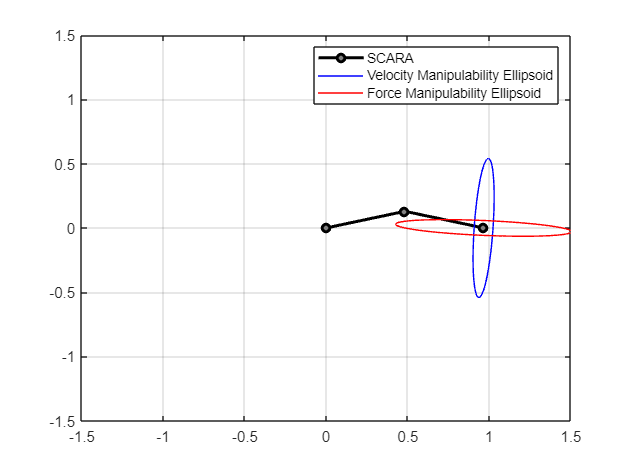

ellipsoids(scara,qt4);

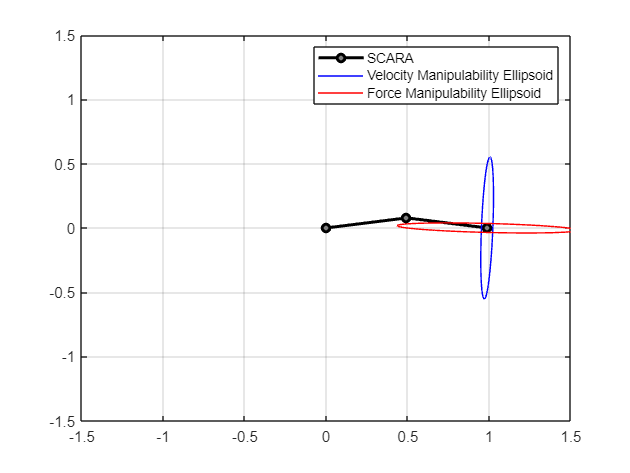

ellipsoids(scara,qt5);

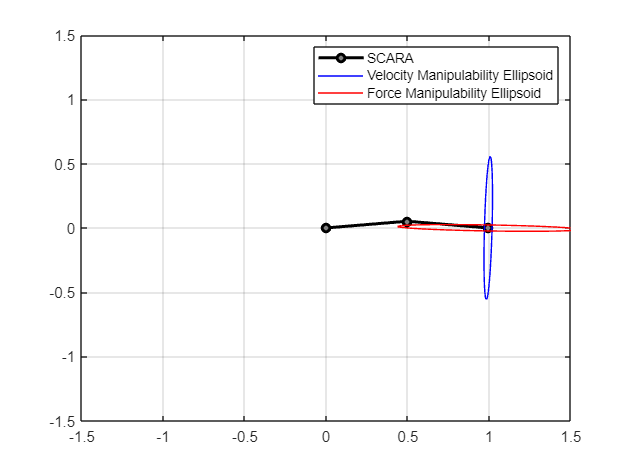

ellipsoids(scara,qt6);

%Manipulability Measure for each pose
w1 = manipulability_measure(qt1)

w1 = 0.1017

w2 = manipulability_measure(qt2)

w2 = 0.2165

w3 = manipulability_measure(qt3)

w3 = 0.2165

w4 = manipulability_measure(qt4)

w4 = 0.1250

w5 = manipulability_measure(qt5)

w5 = 0.0773

w6 = manipulability_measure(qt6)

w6 = 0.0520

### Trajectory Planning

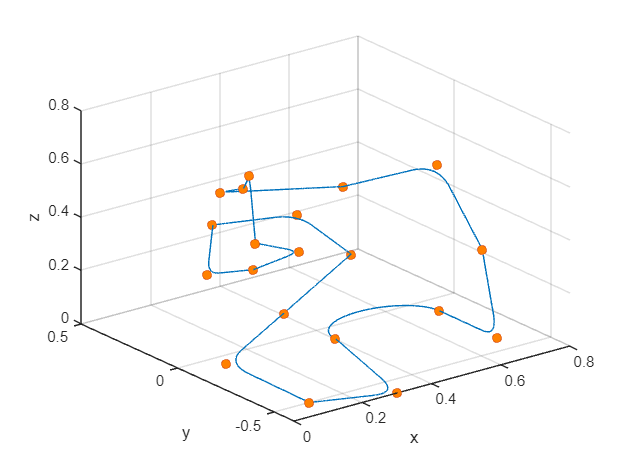

%Points Coordinates
p1 = [0.1 -0.5 0]';
p2 = [0.3 -0.6 0]'; %Via Point
p3 = [0.4 -0.1 0]'; 
p4 = [0.7 -0.1 0]';
p5 = [0.7 -0.4 0]'; %Via Point
p6 = [0.6 -0.5 0.4]';
p7 = [0.75 0 0.5]'; %Via Point
p8 = [0.7 0.4 0.3]';
p9 = [0.4 0.5 0.35]'; %Via Point
p10 = [0.3 0.2 0.5]'; 
p11= [0.15 -0.1 0.7]'; %Via Point 
p12 = [0 -0.4 0.6]';
p13 = [0.1 -0.45 0.55]'; %Via Point
p14 = [0.05 -0.3 0.45]';
p15 = [0 -0.15 0.4]'; %Via Point
p16 = [0.1 0 0.5]';
p17 = [0.4 0.1 0.4]'; %Via Point
p18 = [0.5 0 0.25]';
p19 = [0.25 -0.1 0.15]';
p20 = [0 -0.25 0.1]'; %Via Point
p21 = [0.1 -0.5 0]';

%Phi Angle
phi1=0;
phi2=pi/2;
phi3=0;
phi4=pi/2;
phi5=0;

%Vectors of points and angles
p = [p1 p2 p3 p4 p5 p6 p7 p8 p9 p10 p11 p12 p13 p14 p15 p16 p17 p18 p19 p20 p21];
phi=[phi1 phi2 phi3 phi4 phi5];

%Time Vector (It has been assumed that each segment is completed in 2 seconds)
tk = 0:2:40;

%Segment Computation

[s1 ,s1dot, s1dotdot] = trapezoidal(p(:,1),p(:,2),tk(1),tk(2),tk(end),0,0,0,0,0);
P1 = p(:,1)+(s1.*(p(:,2)-p(:,1)))/norm(p(:,2)-p(:,1));
P1dot = (s1dot.*(p(:,2)-p(:,1)))/norm(p(:,2)-p(:,1));
P1dotdot = (s1dotdot.*(p(:,2)-p(:,1)))/norm(p(:,2)-p(:,1));

%Via Point
[s2 ,s2dot, s2dotdot] = trapezoidal(p(:,2),p(:,3),tk(2),tk(3),tk(end),0,1,0,0,0.7);
P2 = (s2.*(p(:,3)-p(:,2)))/norm(p(:,3)-p(:,2));
P2dot = (s2dot.*(p(:,3)-p(:,2)))/norm(p(:,3)-p(:,2));
P2dotdot = (s2dotdot.*(p(:,3)-p(:,2)))/norm(p(:,3)-p(:,2));

%Circular Portion
R = [-1 0 0;
      0 1 0;
      0 0 1];
radius = 0.15; %(p4_x-p3_x)/2
C = (p(:,3)+p(:,4))./2; %Center

[s3,s3dot,s3dotdot] = trapezoidal(p(:,3),p(:,4),tk(3),tk(4),tk(end),1,0,radius,pi,0);
Pp = [radius*cos(s3/radius); radius*sin(s3/radius); zeros(1,length(s3))];
P3 = C+R*Pp;
Pdotp = [-s3dot.*sin(s3/radius); s3dot.*cos(s3/radius); zeros(1,length(s3))];
P3dot = R*Pdotp;
Pdotdotp = [-((s3dot.^2).*cos(s3/radius))/radius-s3dotdot.*sin(s3/radius); -((s3dot.^2).*sin(s3/radius))/radius+s3dotdot.*cos(s3/radius); zeros(1,length(s3))];
P3dotdot = R*Pdotdotp;

[s4,s4dot,s4dotdot] = trapezoidal(p(:,4),p(:,5),tk(4),tk(5),tk(end),0,0,0,0,0);
P4 = p(:,4) + (s4.*(p(:,5)-p(:,4)))/norm(p(:,5)-p(:,4));
P4dot = (s4dot.*(p(:,5)-p(:,4)))/norm(p(:,5)-p(:,4));
P4dotdot = (s4dotdot.*(p(:,5)-p(:,4)))/norm(p(:,5)-p(:,4));

%Via Point
[s5,s5dot,s5dotdot] = trapezoidal(p(:,5),p(:,6),tk(5),tk(6),tk(end),0,1,0,0,0.7);
P5 = (s5.*(p(:,6)-p(:,5)))/norm(p(:,6)-p(:,5));
P5dot = (s5dot.*(p(:,6)-p(:,5)))/norm(p(:,6)-p(:,5));
P5dotdot = (s5dotdot.*(p(:,6)-p(:,5)))/norm(p(:,6)-p(:,5));

[s6,s6dot,s6dotdot] = trapezoidal(p(:,6),p(:,7),tk(6),tk(7),tk(end),0,0,0,0,0);
P6 = (s6.*(p(:,7)-p(:,6)))/norm(p(:,7)-p(:,6));
P6dot = (s6dot.*(p(:,7)-p(:,6)))/norm(p(:,7)-p(:,6));
P6dotdot = (s6dotdot.*(p(:,7)-p(:,6)))/norm(p(:,7)-p(:,6));

%Via Point
[s7,s7dot,s7dotdot] = trapezoidal(p(:,7),p(:,8),tk(7),tk(8),tk(end),0,1,0,0,0.7);
P7 = (s7.*(p(:,8)-p(:,7)))/norm(p(:,8)-p(:,7));
P7dot = (s7dot.*(p(:,8)-p(:,7)))/norm(p(:,8)-p(:,7));
P7dotdot = (s7dotdot.*(p(:,8)-p(:,7)))/norm(p(:,8)-p(:,7));

[s8,s8dot,s8dotdot] = trapezoidal(p(:,8),p(:,9),tk(8),tk(9),tk(end),0,0,0,0,0);
P8 = (s8.*(p(:,9)-p(:,8)))/norm(p(:,9)-p(:,8));
P8dot = (s8dot.*(p(:,9)-p(:,8)))/norm(p(:,9)-p(:,8));
P8dotdot = (s8dotdot.*(p(:,9)-p(:,8)))/norm(p(:,9)-p(:,8));

%Via Point
[s9,s9dot,s9dotdot] = trapezoidal(p(:,9),p(:,10),tk(9),tk(10),tk(end),0,1,0,0,0.7);
P9 =(s9.*(p(:,10)-p(:,9)))/norm(p(:,10)-p(:,9));
P9dot = (s9dot.*(p(:,10)-p(:,9)))/norm(p(:,10)-p(:,9));
P9dotdot = (s9dotdot.*(p(:,10)-p(:,9)))/norm(p(:,10)-p(:,9));

[s10,s10dot,s10dotdot] = trapezoidal(p(:,10),p(:,11),tk(10),tk(11),tk(end),0,0,0,0,0);
P10 = (s10.*(p(:,11)-p(:,10)))/norm(p(:,11)-p(:,10));
P10dot = (s10dot.*(p(:,11)-p(:,10)))/norm(p(:,11)-p(:,10));
P10dotdot = (s10dotdot.*(p(:,11)-p(:,10)))/norm(p(:,11)-p(:,10));

%Via Point
[s11 ,s11dot, s11dotdot] = trapezoidal(p(:,11),p(:,12),tk(11),tk(12),tk(end),0,1,0,0,0.7);
P11 = (s11.*(p(:,12)-p(:,11)))/norm(p(:,12)-p(:,11));
P11dot = (s11dot.*(p(:,12)-p(:,11)))/norm(p(:,12)-p(:,11));
P11dotdot = (s11dotdot.*(p(:,12)-p(:,11)))/norm(p(:,12)-p(:,11));

[s12 ,s12dot, s12dotdot] = trapezoidal(p(:,12),p(:,13),tk(12),tk(13),tk(end),0,0,0,0,0);
P12 = (s12.*(p(:,13)-p(:,12)))/norm(p(:,13)-p(:,12));
P12dot = (s12dot.*(p(:,13)-p(:,12)))/norm(p(:,13)-p(:,12));
P12dotdot = (s12dotdot.*(p(:,13)-p(:,12)))/norm(p(:,13)-p(:,12));

%Via Point
[s13 ,s13dot, s13dotdot] = trapezoidal(p(:,13),p(:,14),tk(13),tk(14),tk(end),0,1,0,0,0.7);
P13 = (s13.*(p(:,14)-p(:,13)))/norm(p(:,14)-p(:,13));
P13dot =  (s13dot.*(p(:,14)-p(:,13)))/norm(p(:,14)-p(:,13));
P13dotdot = (s13dotdot.*(p(:,14)-p(:,13)))/norm(p(:,14)-p(:,13));

[s14 ,s14dot, s14dotdot] = trapezoidal(p(:,14),p(:,15),tk(14),tk(15),tk(end),0,0,0,0,0);
P14 = (s14.*(p(:,15)-p(:,14)))/norm(p(:,15)-p(:,14));
P14dot = (s14dot.*(p(:,15)-p(:,14)))/norm(p(:,15)-p(:,14));
P14dotdot = (s14dotdot.*(p(:,15)-p(:,14)))/norm(p(:,15)-p(:,14));

%Via Point
[s15 ,s15dot, s15dotdot] = trapezoidal(p(:,15),p(:,16),tk(15),tk(16),tk(end),0,1,0,0,0.7);
P15 = (s15.*(p(:,16)-p(:,15)))/norm(p(:,16)-p(:,15));
P15dot = (s15dot.*(p(:,16)-p(:,15)))/norm(p(:,16)-p(:,15));
P15dotdot = (s15dotdot.*(p(:,16)-p(:,15)))/norm(p(:,16)-p(:,15));

[s16 ,s16dot, s16dotdot] = trapezoidal(p(:,16),p(:,17),tk(16),tk(17),tk(end),0,0,0,0,0);
P16 = (s16.*(p(:,17)-p(:,16)))/norm(p(:,17)-p(:,16));
P16dot = (s16dot.*(p(:,17)-p(:,16)))/norm(p(:,17)-p(:,16));
P16dotdot = (s16dotdot.*(p(:,17)-p(:,16)))/norm(p(:,17)-p(:,16));

%Via Point
[s17 ,s17dot, s17dotdot] = trapezoidal(p(:,17),p(:,18),tk(17),tk(18),tk(end),0,1,0,0,0.7);
P17 = (s17.*(p(:,18)-p(:,17)))/norm(p(:,18)-p(:,17));
P17dot = (s17dot.*(p(:,18)-p(:,17)))/norm(p(:,18)-p(:,17));
P17dotdot = (s17dotdot.*(p(:,18)-p(:,17)))/norm(p(:,18)-p(:,17));

[s18 ,s18dot, s18dotdot] = trapezoidal(p(:,18),p(:,19),tk(18),tk(19),tk(end),0,0,0,0,0);
P18 = (s18.*(p(:,19)-p(:,18)))/norm(p(:,19)-p(:,18));
P18dot = (s18dot.*(p(:,19)-p(:,18)))/norm(p(:,19)-p(:,18));
P18dotdot = (s18dotdot.*(p(:,19)-p(:,18)))/norm(p(:,19)-p(:,18));

[s19 ,s19dot, s19dotdot] = trapezoidal(p(:,19),p(:,20),tk(19),tk(20),tk(end),0,0,0,0,0);
P19 = (s19.*(p(:,20)-p(:,19)))/norm(p(:,20)-p(:,19));
P19dot = (s19dot.*(p(:,20)-p(:,19)))/norm(p(:,20)-p(:,19));
P19dotdot = (s19dotdot.*(p(:,20)-p(:,19)))/norm(p(:,20)-p(:,19));

%Via Point
[s20 ,s20dot, s20dotdot] = trapezoidal(p(:,20),p(:,21),tk(20),tk(21),tk(end),0,1,0,0,0.7);
P20 = (s20.*(p(:,21)-p(:,20)))/norm(p(:,21)-p(:,20));
P20dot = (s20dot.*(p(:,21)-p(:,20)))/norm(p(:,21)-p(:,20));
P20dotdot = (s20dotdot.*(p(:,21)-p(:,20)))/norm(p(:,21)-p(:,20));

%Combine Trajectory Segments
P_A = P1+P2;
P_B = P4+P5+P6+P7+P8+P9+P10+P11+P12+P13+P14+P15+P16+P17+P18+P19+P20;
%Complete Trajetory
P = [P_A(:,1:tk(3)*1000) P3(:,tk(3)*1000+1:tk(4)*1000) P_B(:,tk(4)*1000+1:end)];

%Compute Velocities for each Segment
P_Adot = P1dot+P2dot;
P_Bdot = P4dot+P5dot+P6dot+P7dot+P8dot+P9dot+P10dot+P11dot+P12dot+P13dot+P14dot+P15dot+P16dot+P17dot+P18dot+P19dot+P20dot;
Pdot = [P_Adot(:,1:tk(3)*1000) P3dot(:,tk(3)*1000+1:tk(4)*1000) P_Bdot(:,tk(4)*1000+1:end)];

%Compute Acceleration for each Segment
P_Adotdot = P1dotdot+P2dotdot;
P_Bdotdot = P4dotdot+P5dotdot+P6dotdot+P7dotdot+P8dotdot+P9dotdot+P10dotdot+P11dotdot+P12dotdot+P13dotdot+P14dotdot+P15dotdot+P16dotdot+P17dotdot+P18dotdot+P19dotdot+P20dotdot;
Pdotdot = [P_Adotdot(:,1:tk(3)*1000) P3dotdot(:,tk(3)*1000+1:tk(4)*1000) P_Bdotdot(:,tk(4)*1000+1:end)];

%Combien all time segments
s = s1+s2+s3+s4+s5+s6+s7+s8+s9+s10+s11+s12+s13+s14+s15+s16+s17+s18+s19+s20; %Total Displacement
sdot = s1dot+s2dot+s3dot+s4dot+s5dot+s6dot+s7dot+s8dot+s9dot+s10dot+s11dot+s12dot+s13dot+s14dot+s15dot+s16dot+s17dot+s18dot+s19dot+s20dot; %Total Velocity
sdotdot = s1dotdot+s2dotdot+s3dotdot+s4dotdot+s5dotdot+s6dotdot+s7dotdot+s8dotdot+s9dotdot+s10dotdot+s11dotdot+s12dotdot+s13dotdot+s14dotdot+s15dotdot+s16dotdot+s17dotdot+s18dotdot+s19dotdot+s20dotdot; %Total Acceleration

%Trajectory in the Operational Space
figure
plot3(P(1,:),P(2,:),P(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor',[1 0.5 0])
xlabel('x')
ylabel('y')
zlabel('z')
grid on
hold off

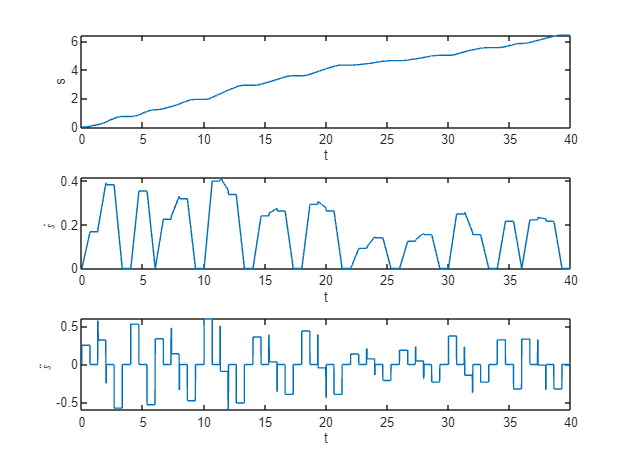

%s, sdot and sdotdot graphs
t=linspace(0,tk(end),tk(end)*1000+1);   %Time Vector
% t=linspace(0,50,50*1000+1);   %New Time Vector

figure
subplot(3,1,1)
plot(t,s)
xlabel('t')
ylabel('s')
xlim([0 40])

subplot(3,1,2)
plot(t,sdot)
xlabel('t')
ylabel('$\dot{s} \ $','Interpreter','latex')
xlim([0 40])

subplot(3,1,3)
plot(t,sdotdot)
xlabel('t')
ylabel('$\ddot{s} \ $','Interpreter','latex')
xlim([0 40])

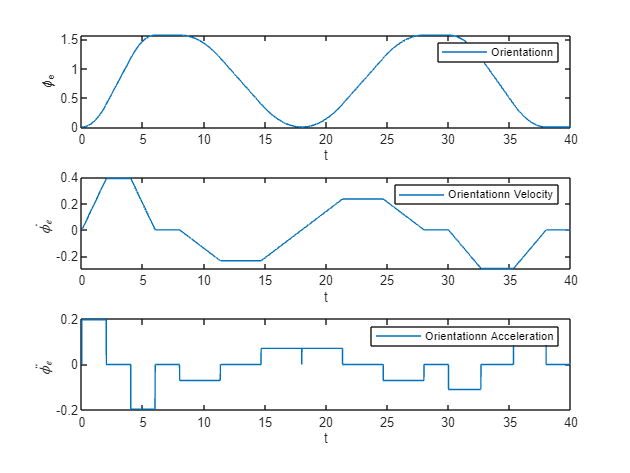

%Orientation Trajectory
[phi1 ,phi1dot, phi1dotdot] = trapezoidal(phi(1),phi(2),tk(1),tk(4),tk(end),0,0,0,0,0);
[phi2 ,phi2dot, phi2dotdot] = trapezoidal(phi(2),phi(3),tk(5),tk(10),tk(end),0,0,0,0,0);
[phi3 ,phi3dot, phi3dotdot] = trapezoidal(phi(3),phi(4),tk(10),tk(15),tk(end),0,0,0,0,0);
[phi4 ,phi4dot, phi4dotdot] = trapezoidal(phi(4),phi(5),tk(16),tk(20),tk(end),0,0,0,0,0);

%Combine Orientation Segments
phe = phi(1)+phi1.*(phi(2)-phi(1))/norm(phi(2)-phi(1)) + phi2.*(phi(3)-phi(2))/norm(phi(3)-phi(2)) + phi3.*(phi(4)-phi(3))/norm(phi(4)-phi(3)) + phi4.*(phi(5)-phi(4))/norm(phi(5)-phi(4)); %Total Orientation
phedot = phi1dot.*(phi(2)-phi(1))/norm(phi(2)-phi(1)) + phi2dot.*(phi(3)-phi(2))/norm(phi(3)-phi(2)) + phi3dot.*(phi(4)-phi(3))/norm(phi(4)-phi(3)) + phi4dot.*(phi(5)-phi(4))/norm(phi(5)-phi(4)); %Total Orientation Velocity
phedotdot = phi1dotdot.*(phi(2)-phi(1))/norm(phi(2)-phi(1)) + phi2dotdot.*(phi(3)-phi(2))/norm(phi(3)-phi(2)) + phi3dotdot.*(phi(4)-phi(3))/norm(phi(4)-phi(3)) + phi4dotdot.*(phi(5)-phi(4))/norm(phi(5)-phi(4));  %Total Acceleration Velocity

t_o = linspace(0, 40, size(phe,2));
figure
subplot(3,1,1)
plot(t_o, phe);
xlabel('t')
ylabel('\phi_e')
legend ("Orientationn")

subplot(3,1,2)
plot(t_o, phedot);
xlabel('t')
ylabel('$\dot{\phi_e} \ $','Interpreter','latex')
legend ("Orientationn Velocity")

subplot(3,1,3)
plot(t_o, phedotdot);
xlabel('t')
ylabel('$\ddot{\phi_e} \ $','Interpreter','latex')
legend ("Orientationn Acceleration")

## Computation of reference values for position and orientation

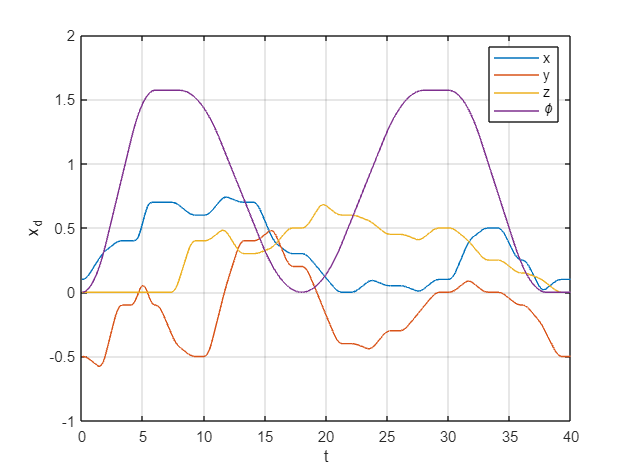

xd = timeseries([P;phe],t);
xddot = timeseries([Pdot;phedot],t);
xddotdot = timeseries([Pdotdot;phedotdot],t);

%xd graph
figure
plot(t,P);
hold on
plot(t,phe);
xlabel('t')
ylabel('x_d')
legend('x','y','z','\phi')
xlim([0 40])
grid on
hold off

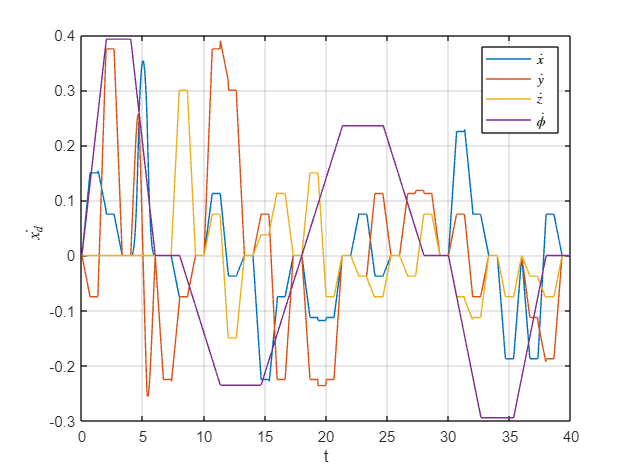

%xddot graph
figure
plot(t,Pdot);
hold on
plot(t,phedot);
xlabel('t')
ylabel('$\dot{x_d} \ $','Interpreter','latex')
legend('$\dot{x} \ $','$\dot{y} \ $','$\dot{z} \ $','$\dot{\phi} \ $','Interpreter','latex')
xlim([0 40])
grid on
hold off

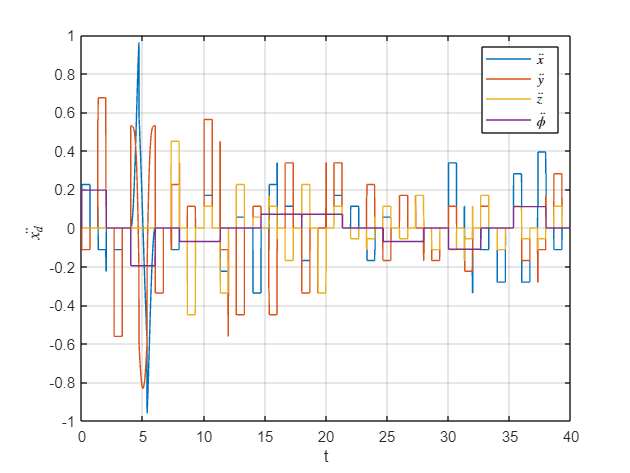

%xddotdot graph
figure
plot(t,Pdotdot);
hold on
plot(t,phedotdot);
xlabel('t')
ylabel('$\ddot{x_d} \ $','Interpreter','latex')
legend('$\ddot{x} \ $','$\ddot{y} \ $','$\ddot{z} \ $','$\ddot{\phi} \ $','Interpreter','latex')
xlim([0 40])
grid on
hold off

## CLIK ALGORITHMS

### CLIK with Jacobian Inverse

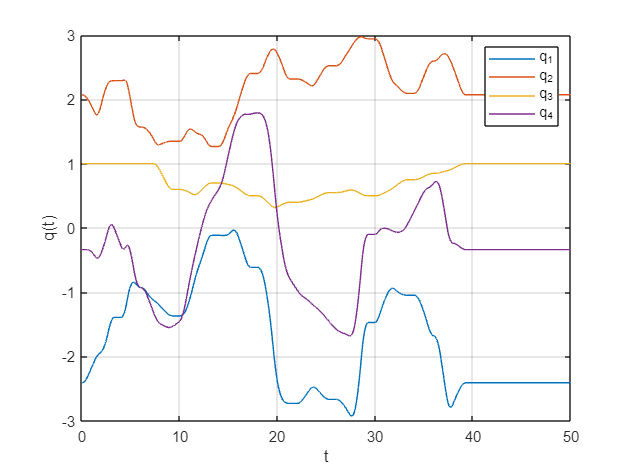

q0=[-2.4088 2.0714 1 -0.3375];  %Initial Condition
K_Jinv = diag([100 100 100 50]);    %Gains Matrix

% t_new=linspace(0,50,50*1000+1);   %New Time Vector
t=linspace(0,50,50*1000+1);   %New Time Vector

out1 = sim("CLIK_Jinv.slx"); %Simulink Scheme

%Joint Variables
figure
plot(t,out1.q_Jinv.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 50])
legend('q_1','q_2','q_3','q_4')
grid on

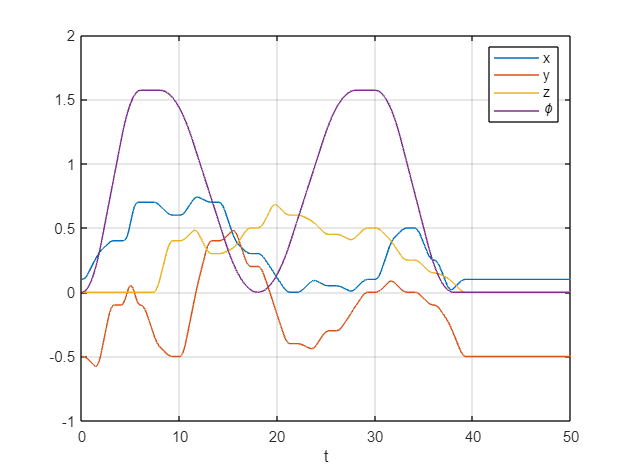

%Operational Space Variables
figure
plot(t,out1.xe_Jinv.signals.values(:,:))
xlabel('t');
legend('x','y','z','\phi')
xlim([0 50])
grid on

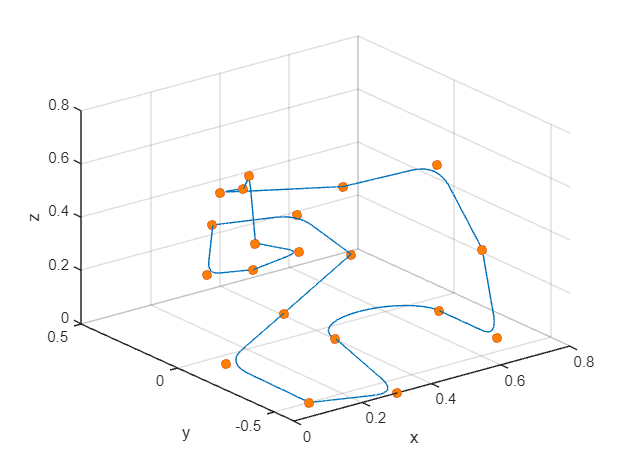

%Trajectory in the Operational Space
figure
plot3(out1.xe_Jinv.signals.values(1,:),out1.xe_Jinv.signals.values(2,:),out1.xe_Jinv.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor',[1 0.5 0])
xlabel('x')
ylabel('y')
zlabel('z')
grid on
hold off

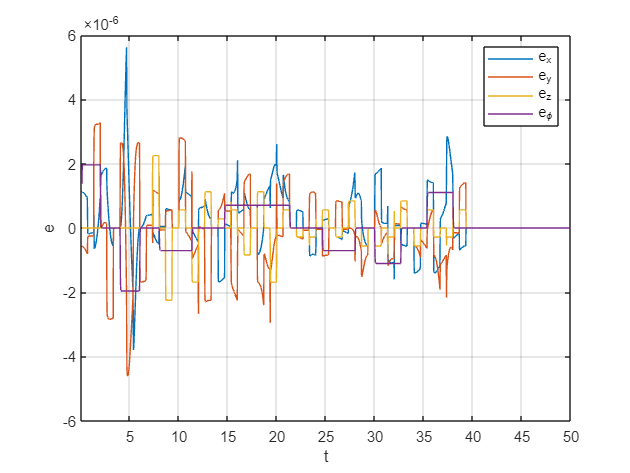

%Error
figure
plot(t,out1.e_Jinv.signals.values(:,:))
xlabel('t');
ylabel('e');
xlim([0.1 50])
legend('e_x','e_y','e_z','e_\phi')
grid on

### CLIK with Jacobian Transpose

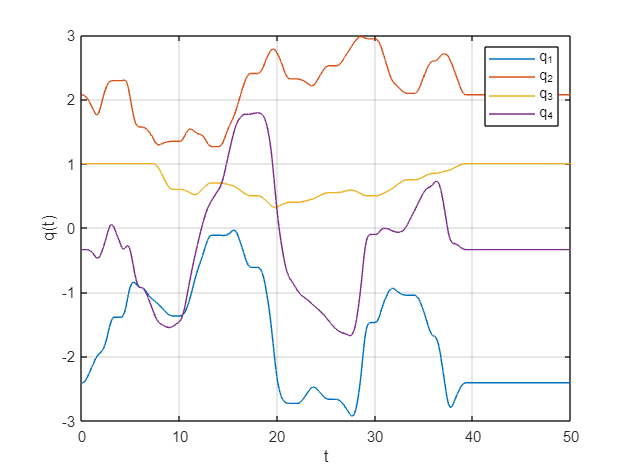

K_Jt = diag([2000 2000 1000 100]);
out2=sim("CLIK_Jt.slx"); %Simulink Scheme

%Joint Variables
figure
plot(t,out2.q_Jt.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 50])
legend('q_1','q_2','q_3','q_4')
grid on

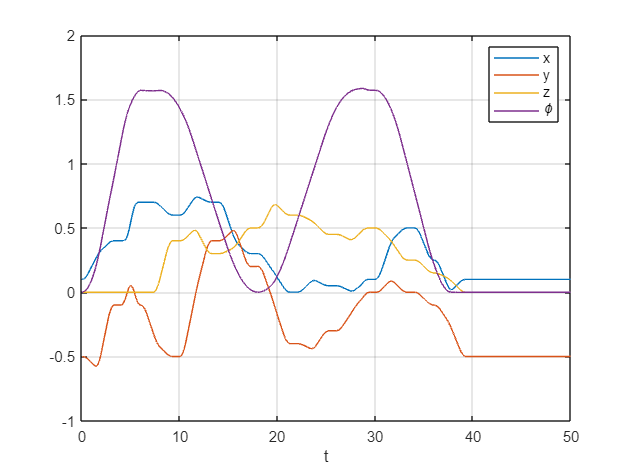

%Operational Space Variables
figure
plot(t,out2.xe_Jt.signals.values(:,:))
xlabel('t');
legend('x','y','z','\phi')
xlim([0 50])
grid on

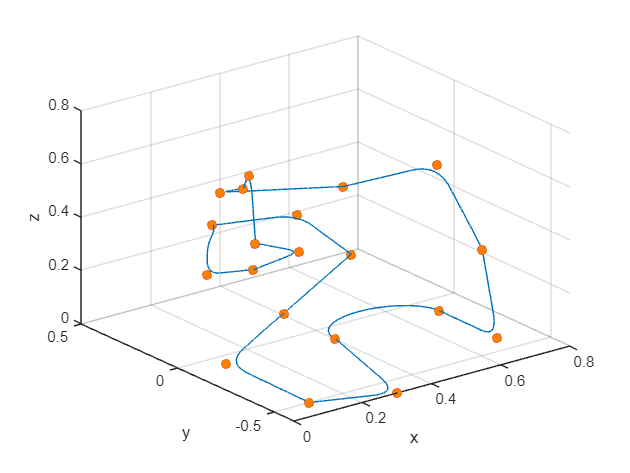

%Trajectory in the Operational Space
figure
plot3(out2.xe_Jt.signals.values(1,:),out2.xe_Jt.signals.values(2,:),out2.xe_Jt.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor',[1 0.5 0])
xlabel('x')
ylabel('y')
zlabel('z')
grid on
hold off

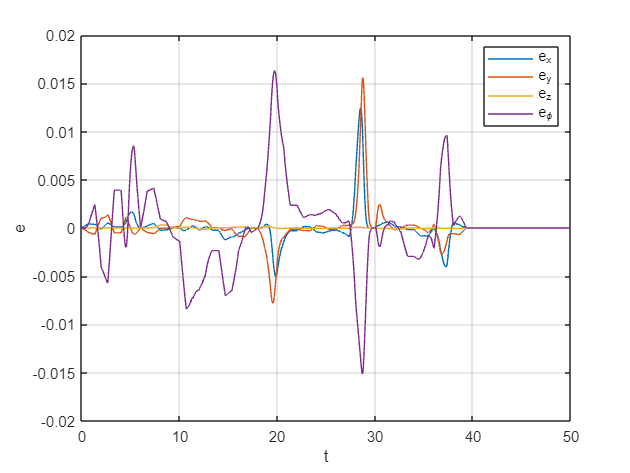

%Error
figure
plot(t,out2.e_Jt.signals.values(:,:))
xlabel('t');
ylabel('e');
xlim([0 50])
legend('e_x','e_y','e_z','e_\phi')
grid on

### CLIK with the Jacobian Pseudo-Inverse

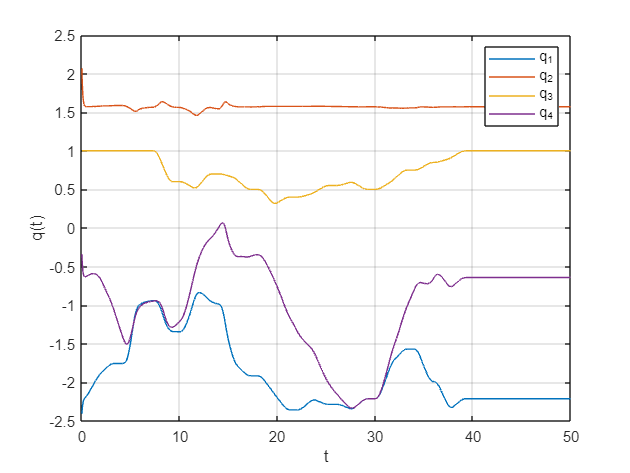

%It is assuming to relax an operational space component
%In this case is assumed to relax the y component (there are only x, z and
%orientation components)
t=linspace(0,tk(end),tk(end)*1000+1);   %Time Vector
% t=linspace(0,50,50*1000+1);   %New Time Vector

Pp = P([1 3],:);
Ppdot = Pdot([1 3],:);
xd_Jpseudo_inv = timeseries([Pp;phe],t);
xddot_Jpseudo_inv = timeseries([Ppdot;phedot],t);
K_Jpseudo_inv = diag([100 100 50]);
k0 = 10;
out3 = sim("CLIK_Jpseudo_inv.slx");
% t=linspace(0,tk(end),tk(end)*1000+1);   %Time Vector
t=linspace(0,50,50*1000+1);   %New Time Vector

%Joint Variables
figure
plot(t,out3.q_Jpseudo_inv.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 50])
legend('q_1','q_2','q_3','q_4')
grid on

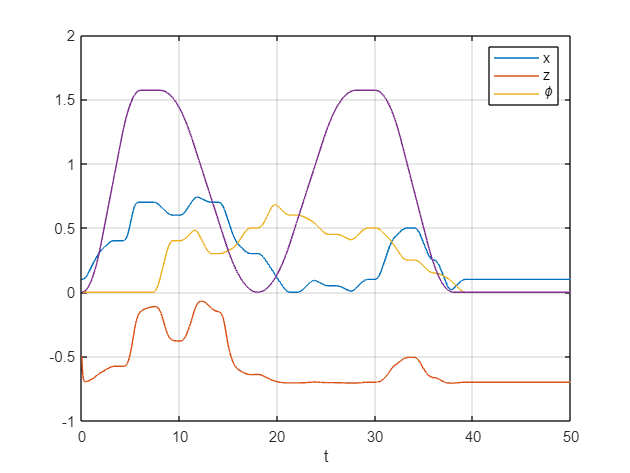

%Operational Space Variables
figure
plot(t,out3.xe_Jpseudo_inv.signals.values(:,:))
xlabel('t');
legend('x','z','\phi')
xlim([0 50])
grid on

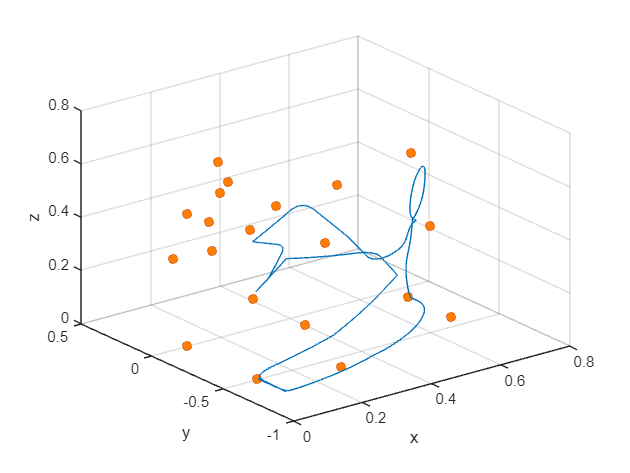

%Trajectory in the Operational Space
figure
plot3(out3.xe_Jpseudo_inv.signals.values(1,:),out3.xe_Jpseudo_inv.signals.values(2,:),out3.xe_Jpseudo_inv.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor',[1 0.5 0])
xlabel('x')
ylabel('y')
zlabel('z')
grid on
hold off

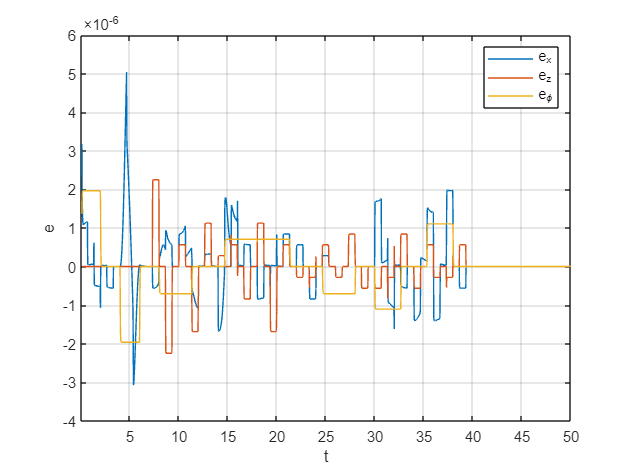

%Error
figure
plot(t,out3.e_Jpseudo_inv.signals.values(:,:))
xlabel('t');
ylabel('e');
xlim([0.1 50])
legend('e_x','e_z','e_\phi')
grid on

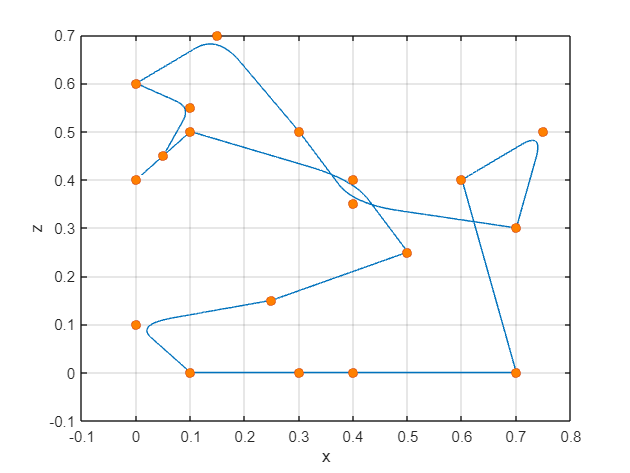

%Trajectory in 2D Operational Space
figure
plot(out3.xe_Jpseudo_inv.signals.values(1,:),out3.xe_Jpseudo_inv.signals.values(3,:))
hold on
plot(p(1,:),p(3,:),'o','MarkerFaceColor',[1 0.5 0])
xlabel('x')
ylabel('z')
grid on
hold off

%Manipulability Measure
w_inv = (sin(out1.q_Jinv.signals.values(2,:))).^2

w_inv =     0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7696    0.7697    0.7697    0.7697    0.7697    0.7697    0.7697    0.7697    0.7697    0.7697    0.7697    0.7697    0.7697    0.7697    0.7697    0.7698    0.7698    0.7698    0.7698    0.7698    0.7698    0.7698    0.7698    0.7698    0.7699    0.7699    0.7699    0.7699    0.7699    0.7699    0.7699    0.7699


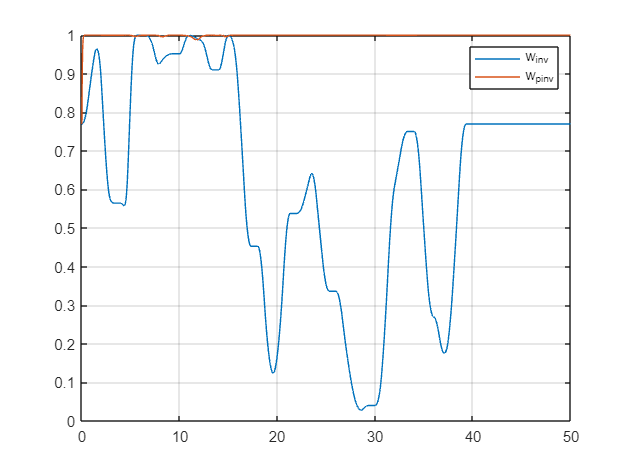

%Do the same for k0 = 0;
w_pinv = (sin(out3.q_Jpseudo_inv.signals.values(2,:))).^2;
figure
plot(t,w_inv)
hold on
xlim([0 50])
plot(t,w_pinv)
legend("w_inv", "w_pinv")
grid on

### 2nd-order CLIK

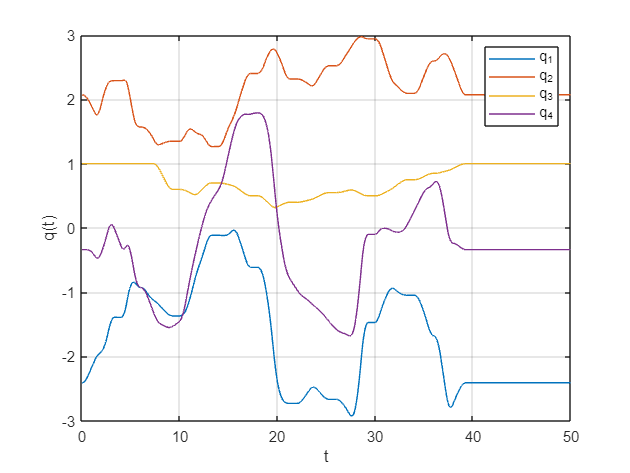

K_P = diag([200 200 200 100]);
K_D = diag([40 40 40 40]);

out4 = sim("CLIK_2nd_order.slx");

%Joint Position Variables
figure
plot(t,out4.q_2nd.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 50])
legend('q_1','q_2','q_3','q_4')
grid on

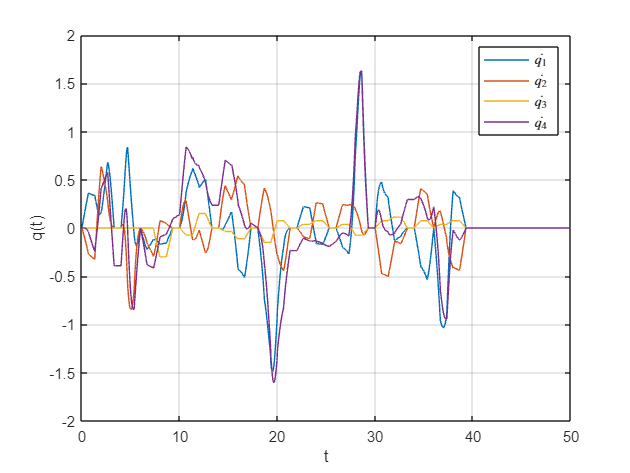

%Joint Velocity Variables
figure
plot(t,out4.qdot_2nd.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 50])
legend('$\dot{q_1} \ $','$\dot{q_2} \ $','$\dot{q_3} \ $','$\dot{q_4} \ $','Interpreter','latex')
grid on

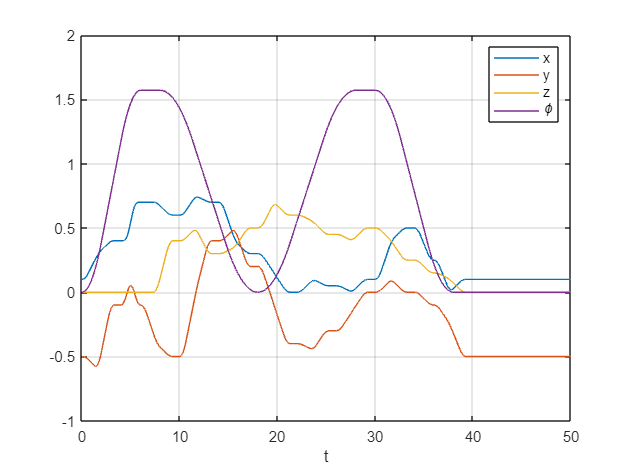

%Joint Acceleration Variables
% figure
% plot(t,out4.qdotdot_2nd.signals.values(:,:))
% xlabel('t')
% ylabel('q(t)')
% xlim([0 50])
% legend('$\ddot{q_1}\','$\ddot{q_2}\','$\ddot{q_3}\','$\ddot{q_4}\','Interpreter','latex')
% grid on

%Operational Space Variables
figure
plot(t,out4.xe_2nd.signals.values(:,:))
xlabel('t');
legend('x','y','z','\phi')
xlim([0 50])
grid on

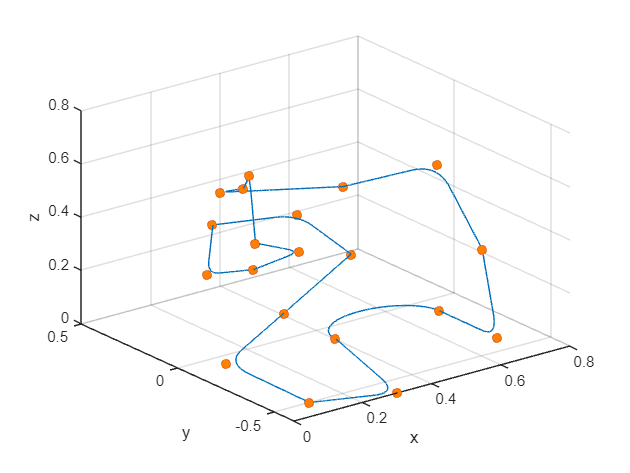

%Trajectory in the Operational Space
figure
plot3(out4.xe_2nd.signals.values(1,:),out4.xe_2nd.signals.values(2,:),out4.xe_2nd.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor',[1 0.5 0])
xlabel('x')
ylabel('y')
zlabel('z')
grid on
hold off

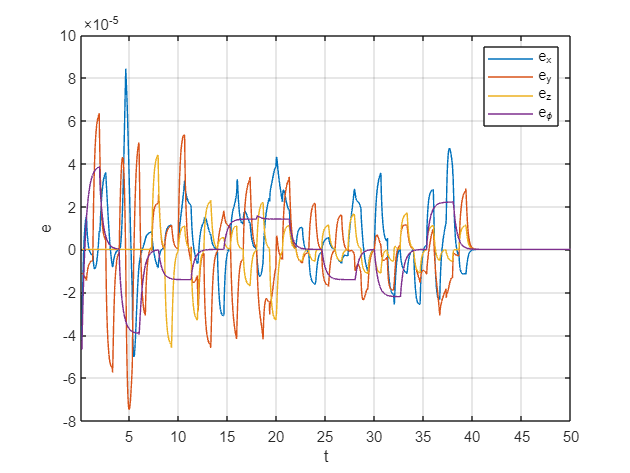

%Position Error
figure
plot(t,out4.e_2nd.signals.values(:,:))
xlabel('t');
ylabel('e');
xlim([0.2 50])
legend('e_x','e_y','e_z','e_\phi')
grid on

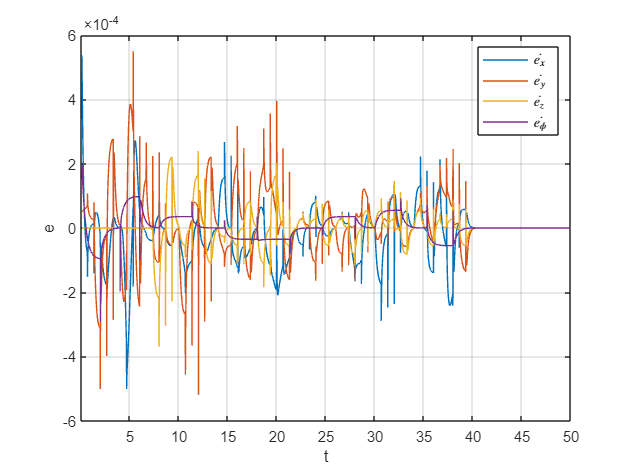

%Velocity Error
figure
plot(t,out4.edot_2nd.signals.values(:,:))
xlabel('t');
ylabel('e');
xlim([0.1 50])
legend('$\dot{e_x} \ $','$\dot{e_y} \ $','$\dot{e_z} \ $','$\dot{e_\phi} \ $','Interpreter','latex')
grid on

## Robust Control

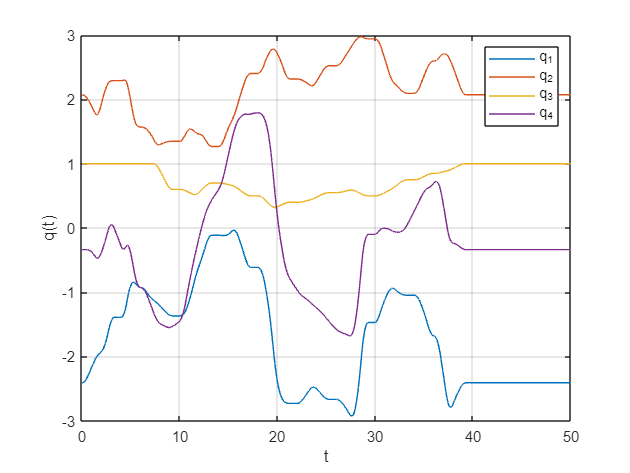

qd = timeseries(out4.q_2nd.signals.values(:,:),t);
qddot = timeseries(out4.qdot_2nd.signals.values(:,:),t);
qddotdot = timeseries(out4.qdotdot_2nd.signals.values(:,:),t);
t=linspace(0,50,50*1000+1);   %New Time Vector

K_P_Rob = diag([1250 1250 2000 1250]);
K_D_Rob = diag([100 100 250 100]);
D = [zeros(4,4); eye(4)];
%It is important to choose Q2 > Q3 (it is given more importance to the
%position instead of velocity)
Q = diag([100 100 100 100 0.1 0.1 0.1 0.1]);
eps = 0.01; %0.001
rhovers = 10;
mload = 3;

out5 = sim("Robust_Control.slx");

%Joint Position Variables
figure
plot(t,out5.q_rob.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 50])
legend('q_1','q_2','q_3','q_4')
grid on

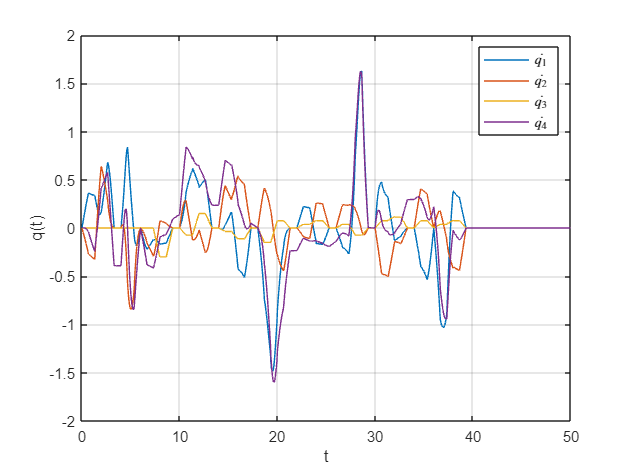

%Joint Velocity Variables
figure
plot(t,out5.qdot_rob.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 50])
legend('$\dot{q_1} \ $','$\dot{q_2} \ $','$\dot{q_3} \ $','$\dot{q_4} \ $','Interpreter','latex')
grid on

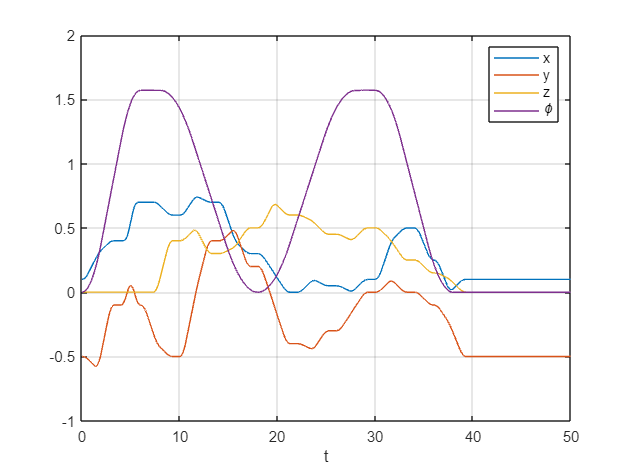

%Operational Space Variables
figure
plot(t,out5.xe_rob.signals.values(:,:))
xlabel('t');
legend('x','y','z','\phi')
xlim([0 50])
grid on

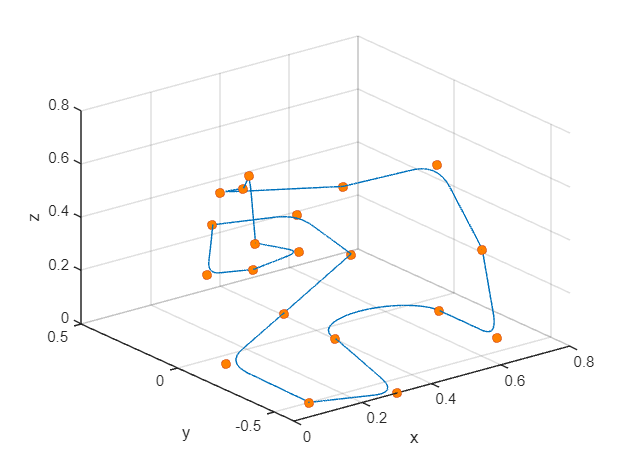

%Trajectory in the Operational Space
figure
plot3(out5.xe_rob.signals.values(1,:),out5.xe_rob.signals.values(2,:),out5.xe_rob.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor',[1 0.5 0])
xlabel('x')
ylabel('y')
zlabel('z')
grid on
hold off

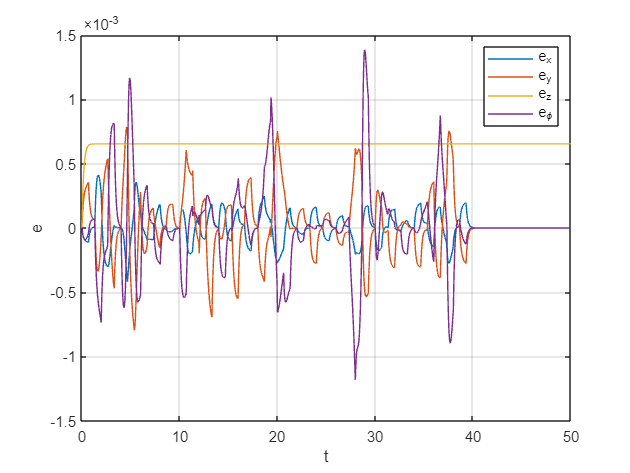

%Position Error
figure
plot(t,out5.qtilde_rob.signals.values(:,:))
xlabel('t');
ylabel('e');
xlim([0 50])
legend('e_x','e_y','e_z','e_\phi')
grid on

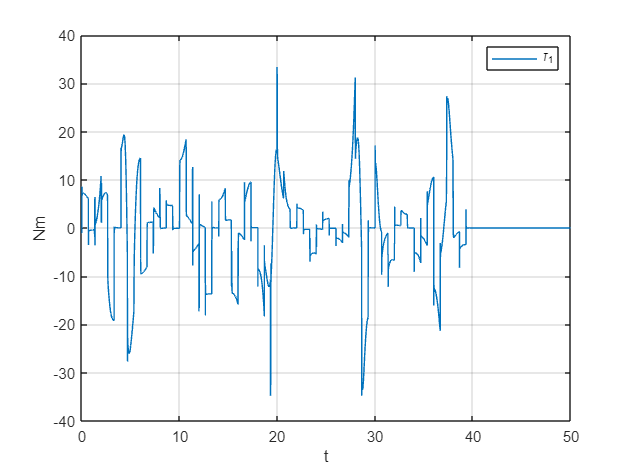

%Velocity Error
% figure
% plot(t,out5.qtildedot_rob.signals.values(:,:))
% xlabel('t');
% ylabel('e');
% xlim([0.1 50])
% legend('$\dot{e_x} \ $','$\dot{e_y} \ $','$\dot{e_z} \ $','$\dot{e_\phi} \ $','Interpreter','latex')
% grid on

%Control (Tau)
figure
plot(out5.u_rob.time,out5.u_rob.signals.values(1,:))
xlabel('t');
ylabel('Nm')
xlim([0 50])
grid on
legend('\tau_1')

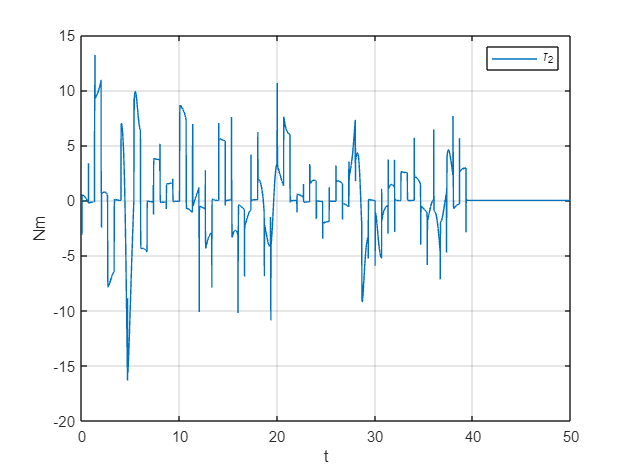

figure
plot(out5.u_rob.time,out5.u_rob.signals.values(2,:))
xlabel('t');
ylabel('Nm')
xlim([0 50])
grid on
legend('\tau_2')

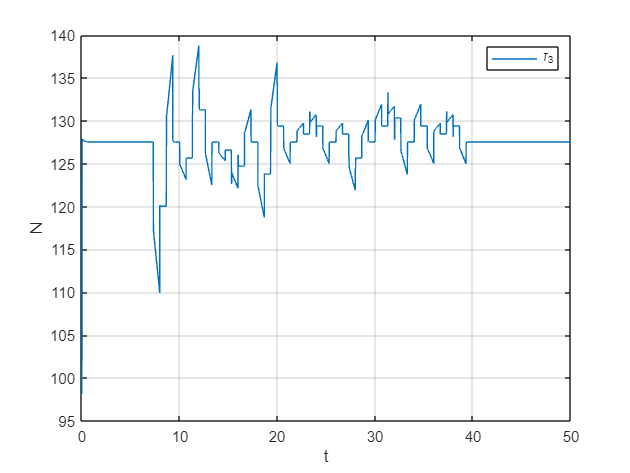

figure
plot(out5.u_rob.time,out5.u_rob.signals.values(3,:))
xlabel('t');
ylabel('N')
xlim([0 50])
grid on
legend('\tau_3')

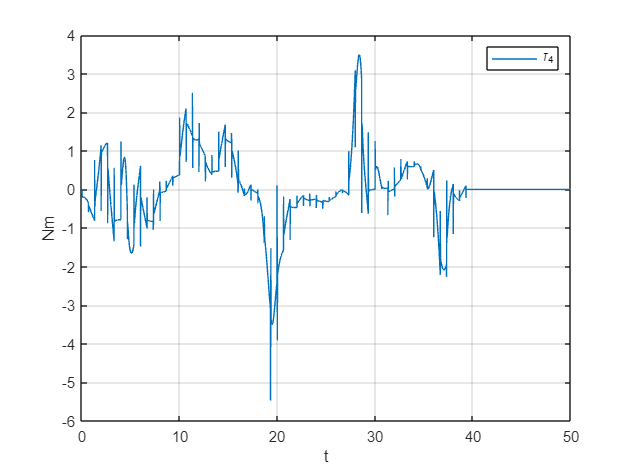

figure
plot(out5.u_rob.time,out5.u_rob.signals.values(4,:))
xlabel('t');
ylabel('Nm')
xlim([0 50])
grid on
legend('\tau_4')

## Adaptive Control

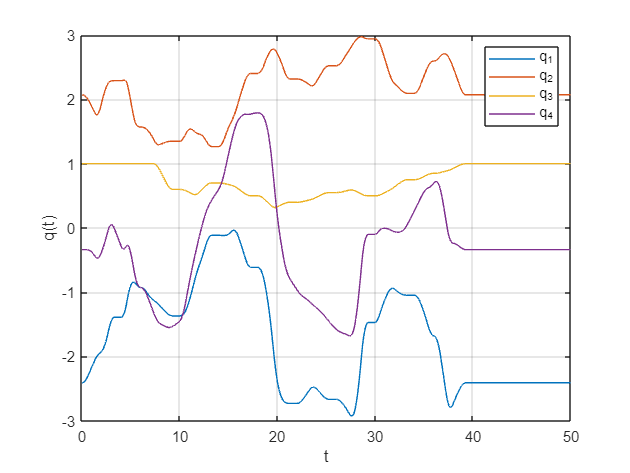

Lambda = diag([80,50,80,50]);

Kpi = diag([1,1,1,1,1,1,1,1,0.001,1,1,0.001,1,1]);
 
K_D_Adapt = diag([1500,1500,1500,1500]);
pi0 = [ml1 Il1 Im1 Fm1 ml2 Il2 Im2 Fm2 ml3 Im3 Fm3 Il4 Im4 Fm4]';
% t = linspace(0,50,50*1000+1);   %New Time Vector

% % Lambda = diag([80,50,80,50]);
% % Kpi = diag([1,1,1,1,1,1,1,1,1,1,1,0.001,0.001,1,1]);
% % K_D_Adapt = diag([1500,1500,1500,1500]);
% % 
% % ml4 = 0;
% % pi0 = [ml1 Il1 Im1 Fm1 ml2 Il2 Im2 Fm2 ml3 Im3 Fm3 ml4 Il4 Im4 Fm4]';

out6 = sim("Adaptive_Control.slx");

%Joint Position Variables
figure
plot(t,out6.q_adapt.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 50])
legend('q_1','q_2','q_3','q_4')
grid on

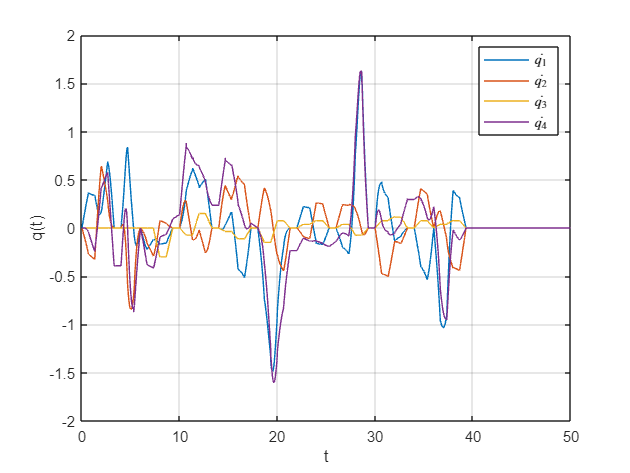

%Joint Velocity Variables
figure
plot(t,out6.qdot_adapt.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 50])
legend('$\dot{q_1} \ $','$\dot{q_2} \ $','$\dot{q_3} \ $','$\dot{q_4} \ $','Interpreter','latex')
grid on

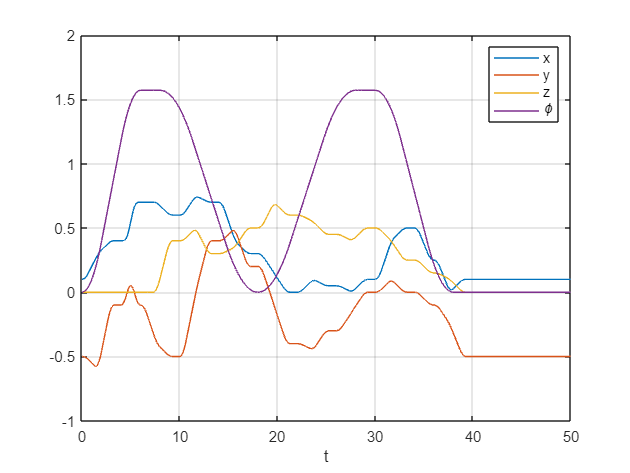

%Operational Space Variables
figure
plot(t,out6.xe_adapt.signals.values(:,:))
xlabel('t');
legend('x','y','z','\phi')
xlim([0 50])
grid on

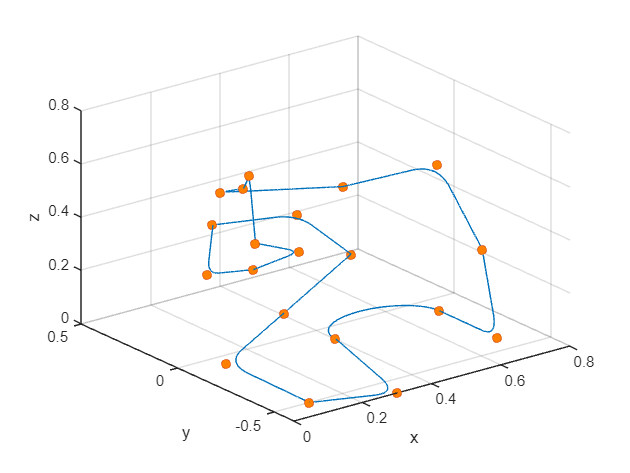

%Trajectory in the Operational Space
figure
plot3(out6.xe_adapt.signals.values(1,:),out6.xe_adapt.signals.values(2,:),out6.xe_adapt.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor',[1 0.5 0])
xlabel('x')
ylabel('y')
zlabel('z')
grid on
hold off

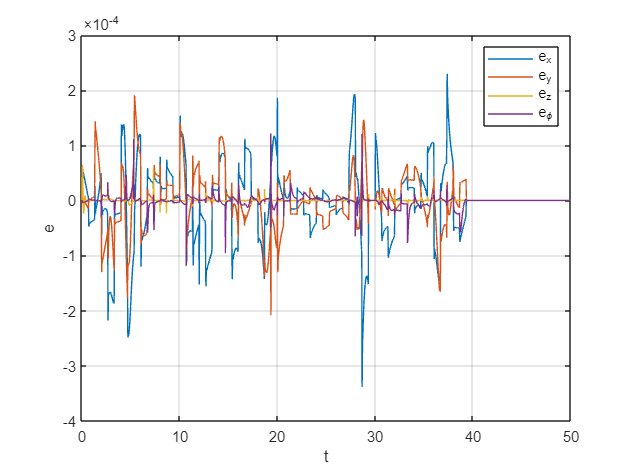

%Position Error
figure
plot(t,out6.qtilde_adapt.signals.values(:,:))
xlabel('t');
ylabel('e');
xlim([0 50])
legend('e_x','e_y','e_z','e_\phi')
grid on

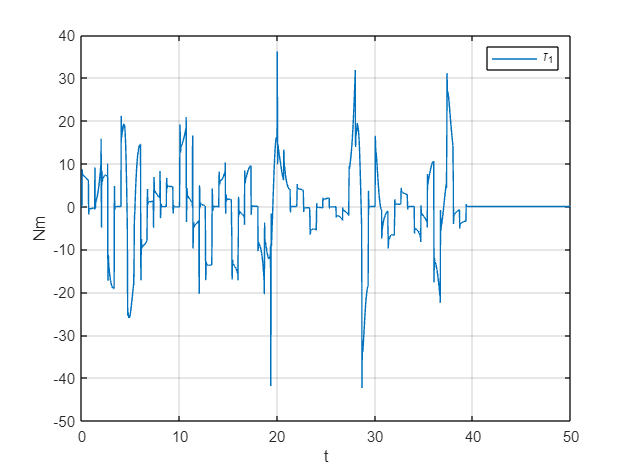

%Velocity Error
% figure
% plot(t,out6.qtildedot_adapt.signals.values(:,:))
% xlabel('t');
% ylabel('e');
% xlim([0.1 50])
% legend('$\dot{e_x} \ $','$\dot{e_y} \ $','$\dot{e_z} \ $','$\dot{e_\phi} \ $','Interpreter','latex')
% grid on

%Control (Tau)
figure
plot(out6.u_adapt.time,out6.u_adapt.signals.values(1,:))
xlabel('t');
ylabel('Nm')
xlim([0 50])
grid on
legend('\tau_1')

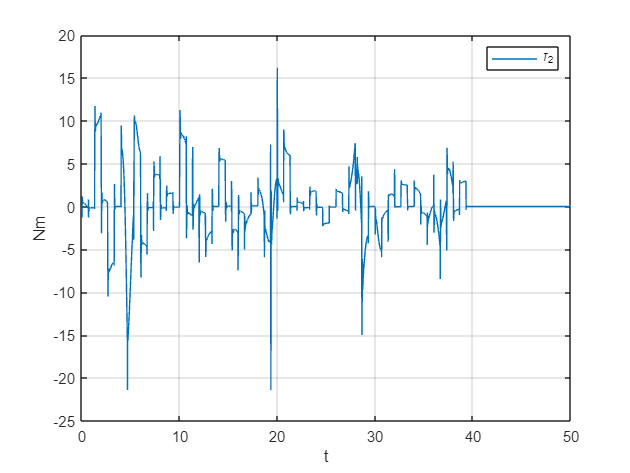

figure
plot(out6.u_adapt.time,out6.u_adapt.signals.values(2,:))
xlabel('t');
ylabel('Nm')
xlim([0 50])
grid on
legend('\tau_2')

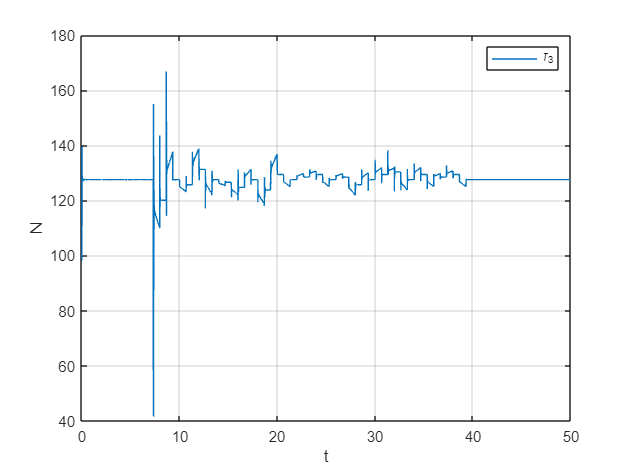

figure
plot(out6.u_adapt.time,out6.u_adapt.signals.values(3,:))
xlabel('t');
ylabel('N')
xlim([0 50])
grid on
legend('\tau_3')

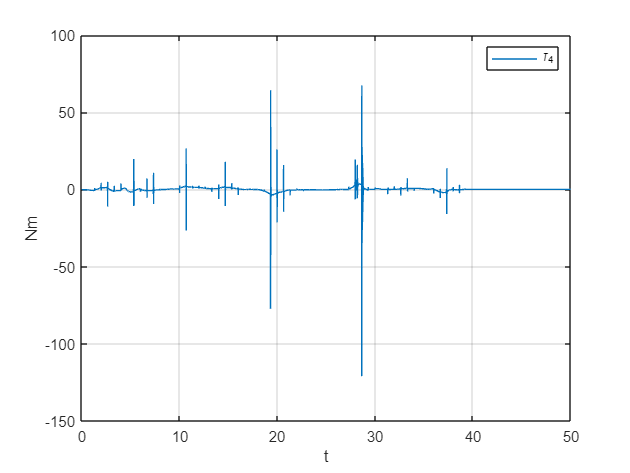

figure
plot(out6.u_adapt.time,out6.u_adapt.signals.values(4,:))
xlabel('t');
ylabel('Nm')
xlim([0 50])
grid on
legend('\tau_4')

### Operational Space Inverse Dynamics Control

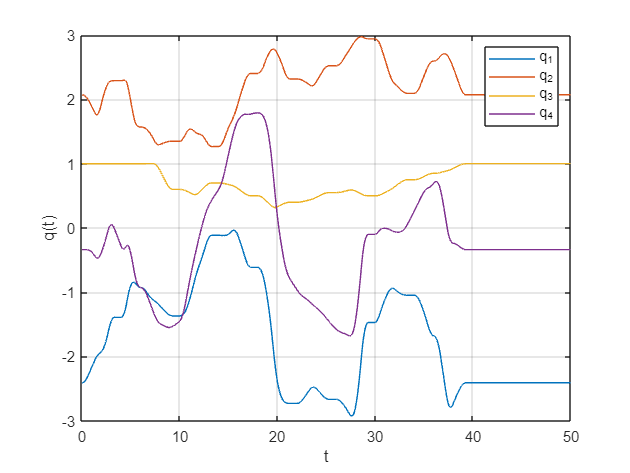

K_P_os_invdyn = diag([1000 1000 8000 200]); 
K_I_os_invdyn = diag([500 500 1000 100]); 
K_D_os_invdyn = diag([100 100 300 50]);

out7 = sim("OS_Inverse_Dynamics_Control.slx");

%Joint Position Variables
figure
plot(t,out7.q_os_invdyn.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 50])
legend('q_1','q_2','q_3','q_4')
grid on

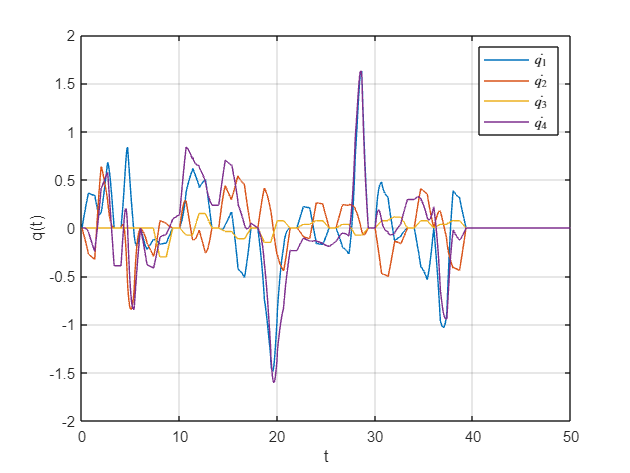

%Joint Velocity Variables
figure
plot(t,out7.qdot_os_invdyn.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 50])
legend('$\dot{q_1} \ $','$\dot{q_2} \ $','$\dot{q_3} \ $','$\dot{q_4} \ $','Interpreter','latex')
grid on

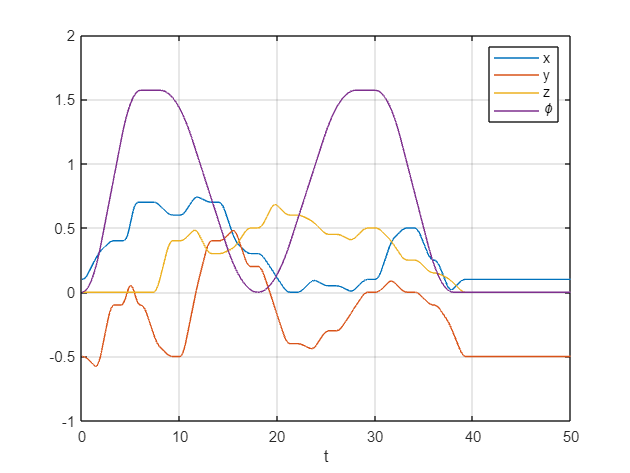

%Operational Space Variables
figure
plot(t,out7.xe_os_invdyn.signals.values(:,:))
xlabel('t');
legend('x','y','z','\phi')
xlim([0 50])
grid on

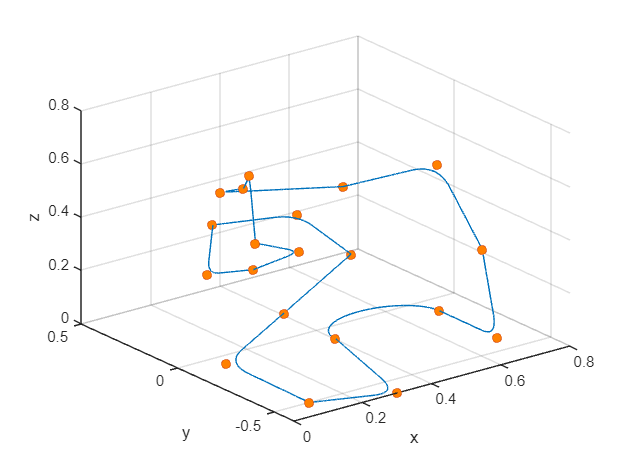

%Trajectory in the Operational Space
figure
plot3(out7.xe_os_invdyn.signals.values(1,:),out7.xe_os_invdyn.signals.values(2,:),out7.xe_os_invdyn.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor',[1 0.5 0])
xlabel('x')
ylabel('y')
zlabel('z')
grid on
hold off

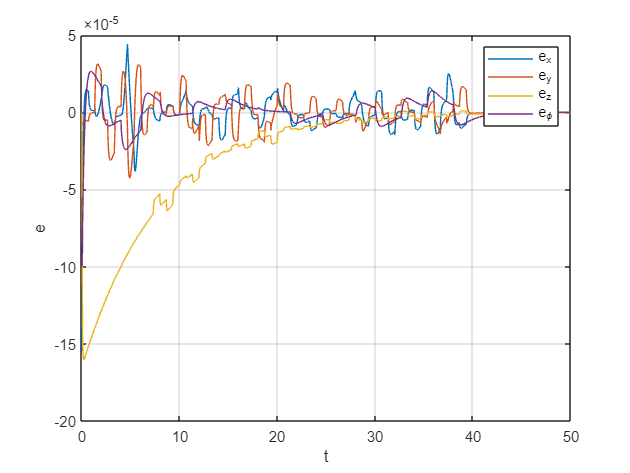

%Position Error
figure
plot(t,out7.xtilde_os_invdyn.signals.values(:,:))
xlabel('t');
ylabel('e');
xlim([0 50])
legend('e_x','e_y','e_z','e_\phi')
grid on

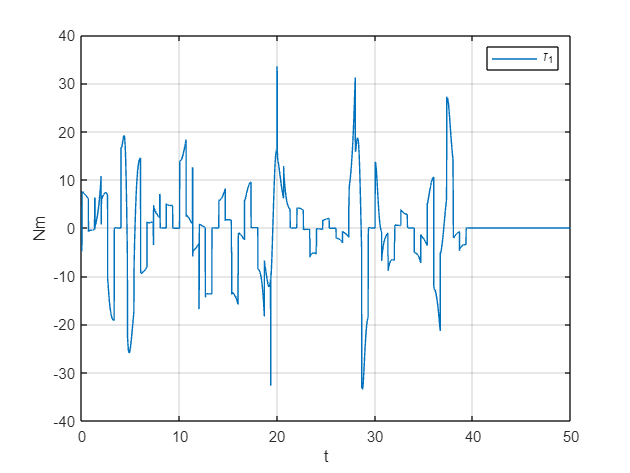

%Velocity Error
% figure
% plot(t,out6.xtildedot_os_invdyn.signals.values(:,:))
% xlabel('t');
% ylabel('e');
% xlim([0.1 50])
% legend('$\dot{e_x} \ $','$\dot{e_y} \ $','$\dot{e_z} \ $','$\dot{e_\phi} \ $','Interpreter','latex')
% grid on

%Control (Tau)
figure
plot(out7.u_os_invdyn.time,out7.u_os_invdyn.signals.values(1,:))
xlabel('t');
ylabel('Nm')
xlim([0 50])
grid on
legend('\tau_1')

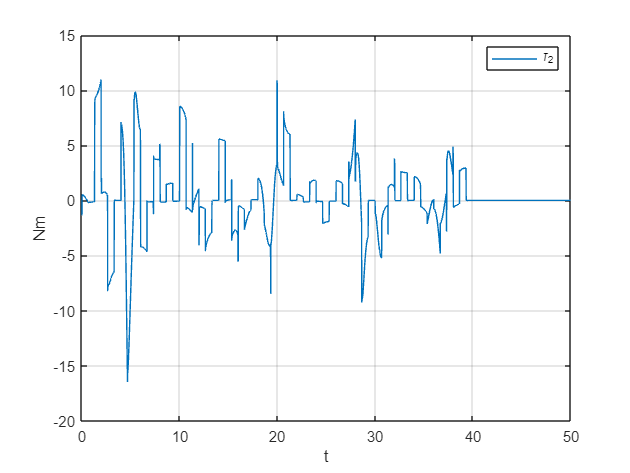

figure
plot(out7.u_os_invdyn.time,out7.u_os_invdyn.signals.values(2,:))
xlabel('t');
ylabel('Nm')
xlim([0 50])
grid on
legend('\tau_2')

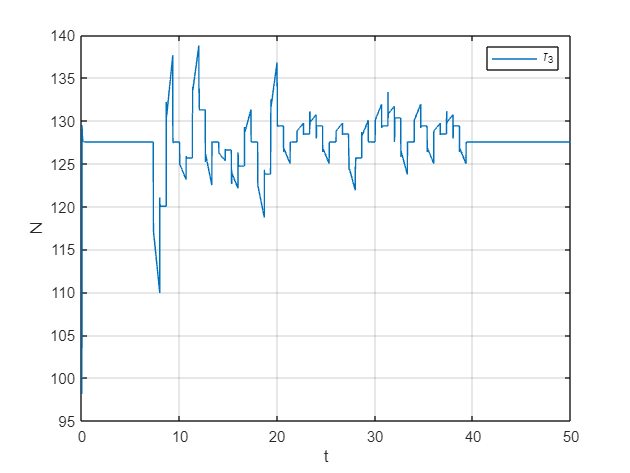

figure
plot(out7.u_os_invdyn.time,out7.u_os_invdyn.signals.values(3,:))
xlabel('t');
ylabel('N')
xlim([0 50])
grid on
legend('\tau_3')

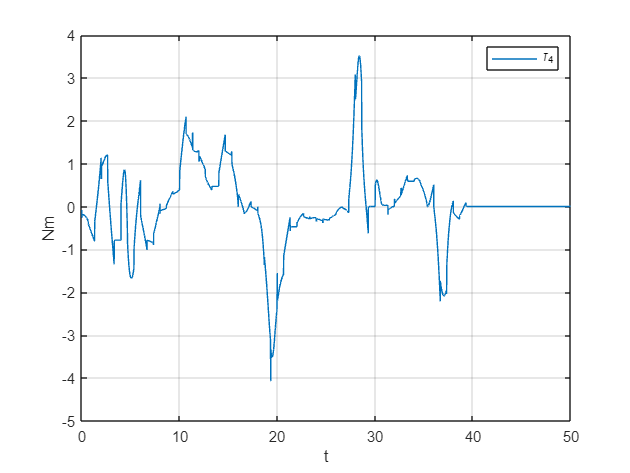

figure
plot(out7.u_os_invdyn.time,out7.u_os_invdyn.signals.values(4,:))
xlabel('t');
ylabel('Nm')
xlim([0 50])
grid on
legend('\tau_4')